syms s
syms h1 h2 real
A=[-10 0;0 -0.1];
c=[1 1];
x0=[10;1];%初期状態
xh0=[0;0];%オブザーバ初期値
h=[h1;h2];

%オブザーバの特性多項式
det(s*eye(2)-(A-h*c))

$$ans = \frac{h_{1}}{10}+10\,h_{2}+\frac{101\,s}{10}+h_{1}\,s+h_{2}\,s+s^{2}+1$$

coeffs(det(s*eye(2)-(A-h*c)),s)

$$ans = \left(\begin{array}{ccc} \frac{h_{1}}{10}+10\,h_{2}+1 & h_{1}+h_{2}+\frac{101}{10} & 1 \end{array}\right)$$


%オブザーバの極を-2,-3としたときの望みの特性多項式
coeffs((s+2)*(s+3),s)

$$ans = \left(\begin{array}{ccc} 6 & 5 & 1 \end{array}\right)$$


%シミュレーション
h=[-5.6;0.56];
eig(A-h*c)

ans =    -3.1307
   -1.9293


X0=[10;1;0;0]

X0 =     10
     1
     0
     0


AA=[A zeros(2);h*c A-h*c]

AA =   -10.0000         0         0         0
         0   -0.1000         0         0
   -5.6000   -5.6000   -4.4000    5.6000
    0.5600    0.5600   -0.5600   -0.6600


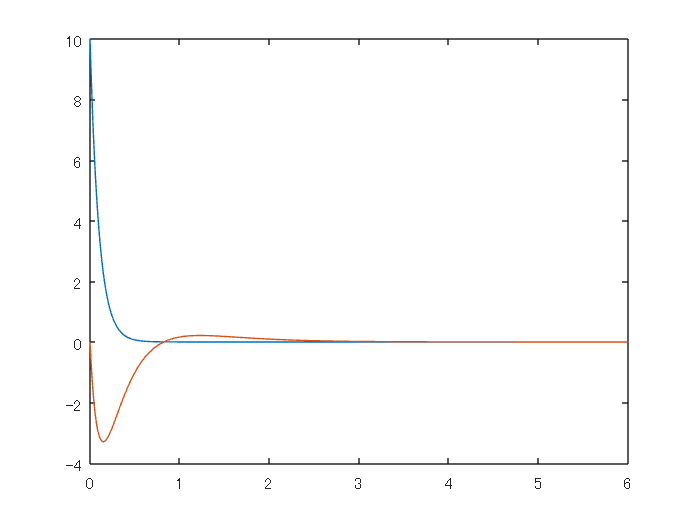

[T,X]=ode45(@(t,X) AA*X,0:0.01:6,X0);
plot(T,X(:,1),T,X(:,3))

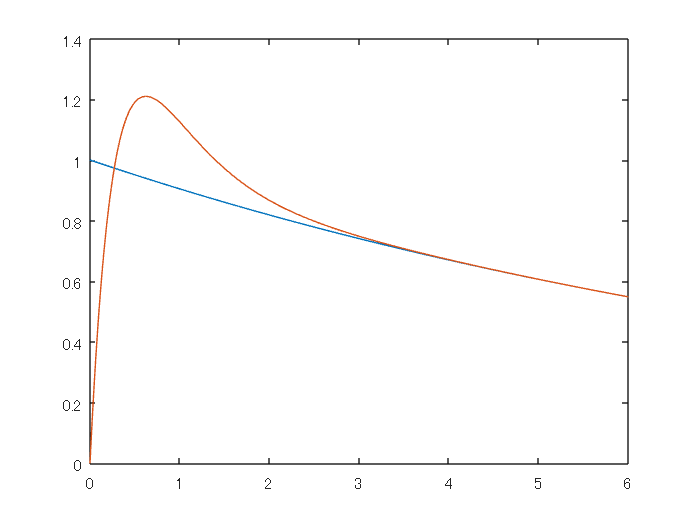

plot(T,X(:,2),T,X(:,4))

%双対システムver
h=[-5.6;0.56];
F=place(A',c',[-1,-40]);
h=F'

h =    27.2727
    3.6273


eig(A-h*c)

ans =   -40.0000
   -1.0000


X0=[10;1;0;0]

X0 =     10
     1
     0
     0


AA=[A zeros(2);h*c A-h*c]

AA =   -10.0000         0         0         0
         0   -0.1000         0         0
   27.2727   27.2727  -37.2727  -27.2727
    3.6273    3.6273   -3.6273   -3.7273


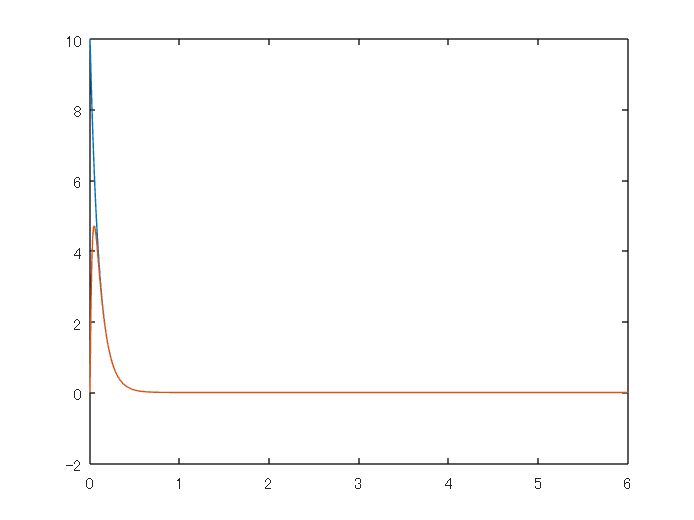

[T,X]=ode45(@(t,X) AA*X,0:0.01:6,X0);
plot(T,X(:,1),T,X(:,3))

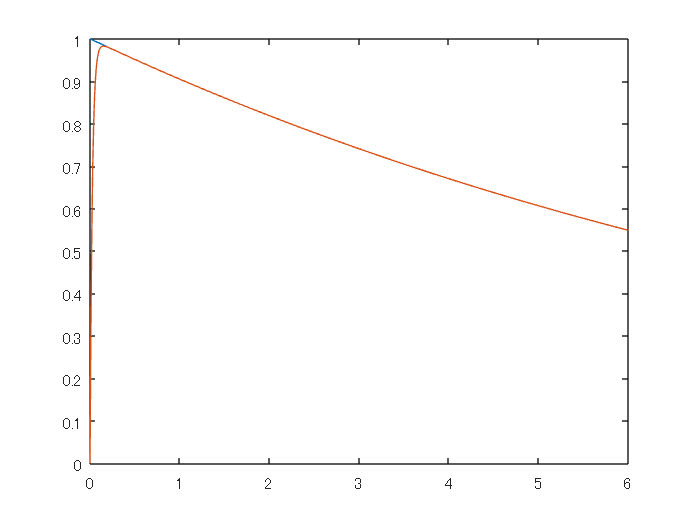

plot(T,X(:,2),T,X(:,4))